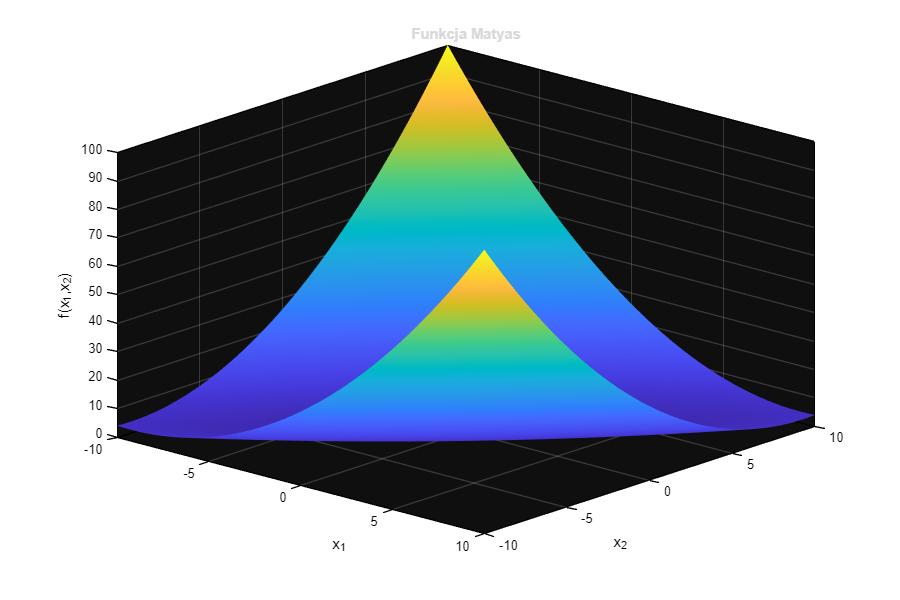

clear; clc; close all;

%% Matyas - powierzchnia

f1 = @(x1,x2) 0.26*(x1.^2+x2.^2)-0.48*x1.*x2;

[x1,x2] = meshgrid(linspace(-10,10,200));
z = f1(x1,x2);

figure('Color','w','Position',[100 100 900 600]);

surf(x1,x2,z,'EdgeColor','none');
colormap(parula);
grid on; box on; view(42,27);

xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1,x_2)');
title('Funkcja Matyas');

ax = gca;
ax.Color = [0.06 0.06 0.06];
ax.XColor = 'k';
ax.YColor = 'k';
ax.ZColor = 'k';
ax.GridColor = [0.7 0.7 0.7];

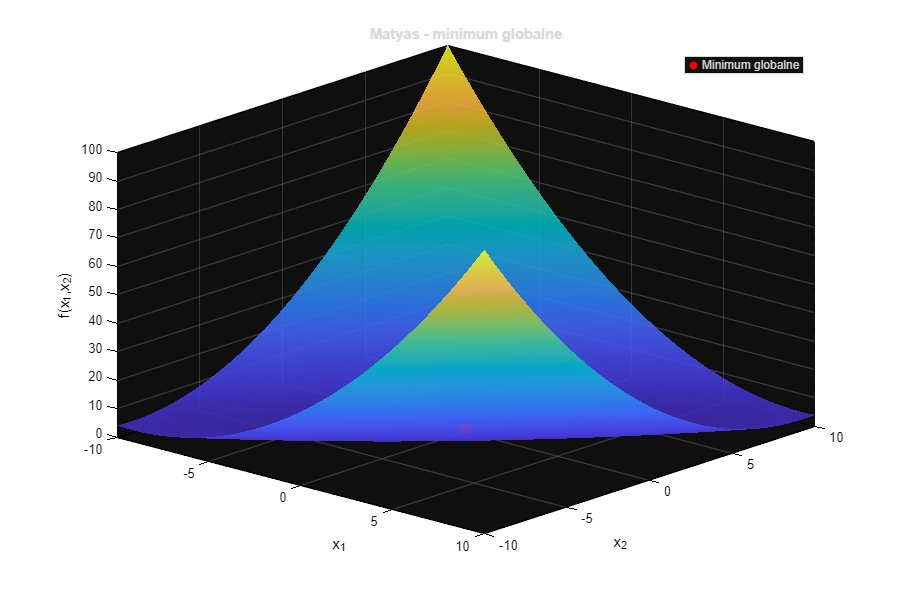


%% Matyas - minimum globalne

figure('Color','w','Position',[140 140 900 600]);

surf(x1,x2,z,'EdgeColor','none','FaceAlpha',0.85, ...
    'HandleVisibility','off');
hold on;

p = scatter3(0,0,0,140,'r','filled','Marker','o');

colormap(parula);
grid on; box on; view(42,27);

xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1,x_2)');
title('Matyas - minimum globalne');

legend(p,'Minimum globalne','Location','northeast');

ax = gca;
ax.Color = [0.06 0.06 0.06];
ax.XColor = 'k';
ax.YColor = 'k';
ax.ZColor = 'k';
ax.GridColor = [0.7 0.7 0.7];

hold off;

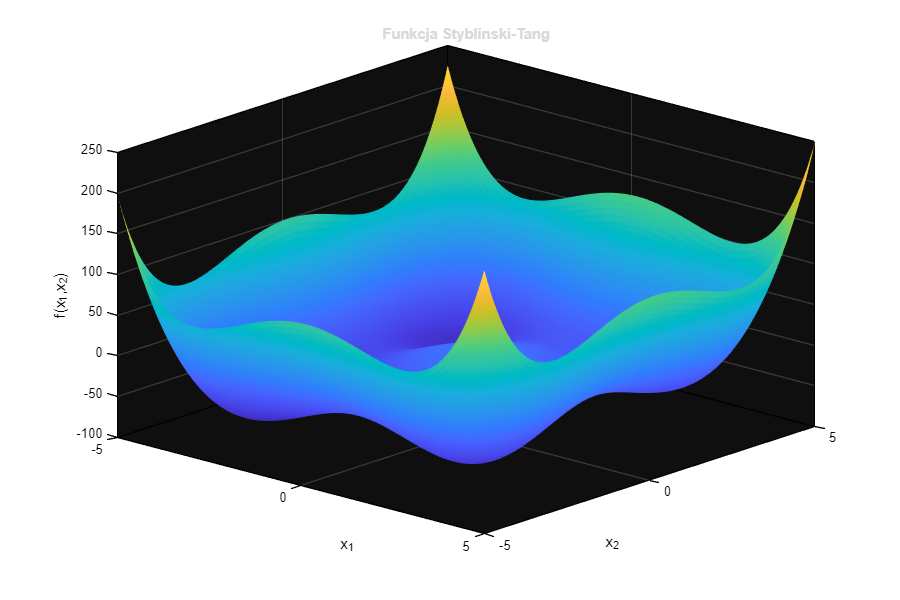


%% Styblinski-Tang - powierzchnia

f2 = @(x1,x2) 0.5*(x1.^4-16*x1.^2+5*x1+x2.^4-16*x2.^2+5*x2);

[x1,x2] = meshgrid(linspace(-5,5,200));
z = f2(x1,x2);

figure('Color','w','Position',[180 180 900 600]);

surf(x1,x2,z,'EdgeColor','none');
colormap(parula);
grid on; box on; view(42,27);

xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1,x_2)');
title('Funkcja Styblinski-Tang');

ax = gca;
ax.Color = [0.06 0.06 0.06];
ax.XColor = 'k';
ax.YColor = 'k';
ax.ZColor = 'k';
ax.GridColor = [0.7 0.7 0.7];

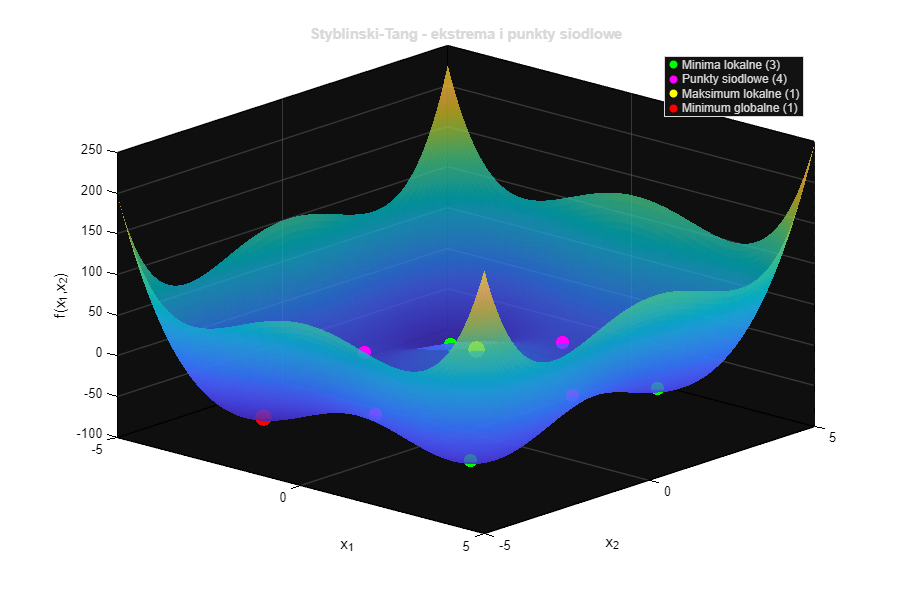


%% Styblinski-Tang - ekstrema i punkty siodlowe

r = sort(roots([1 0 -8 1.25]));

a = r(1);
b = r(2);
c = r(3);

minimum = [a a];

minima = [a c;
          c a;
          c c];

siodla = [a b;
          b a;
          b c;
          c b];

maksimum = [b b];

figure('Color','w','Position',[220 220 900 600]);

surf(x1,x2,z,'EdgeColor','none','FaceAlpha',0.75, ...
    'HandleVisibility','off');
hold on;

p1 = scatter3(minima(:,1),minima(:,2), ...
    f2(minima(:,1),minima(:,2)), ...
    100,'g','filled','Marker','o');

p2 = scatter3(siodla(:,1),siodla(:,2), ...
    f2(siodla(:,1),siodla(:,2)), ...
    100,'m','filled','Marker','o');

p3 = scatter3(maksimum(:,1),maksimum(:,2), ...
    f2(maksimum(:,1),maksimum(:,2)), ...
    150,'y','filled','Marker','o');

p4 = scatter3(minimum(:,1),minimum(:,2), ...
    f2(minimum(:,1),minimum(:,2)), ...
    150,'r','filled','Marker','o');

colormap(parula);
grid on; box on; view(42,27);

xlabel('x_1');
ylabel('x_2');
zlabel('f(x_1,x_2)');
title('Styblinski-Tang - wszystkie punkty stacjonarne');

legend([p1 p2 p3 p4], ...
    'Minima lokalne (3)', ...
    'Punkty siodlowe (4)', ...
    'Maksimum lokalne (1)', ...
    'Minimum globalne (1)', ...
    'Location','northeast');

ax = gca;
ax.Color = [0.06 0.06 0.06];
ax.XColor = 'k';
ax.YColor = 'k';
ax.ZColor = 'k';
ax.GridColor = [0.7 0.7 0.7];

hold off;